# **Numerical Integration (Simpson's 1/3)**

Function

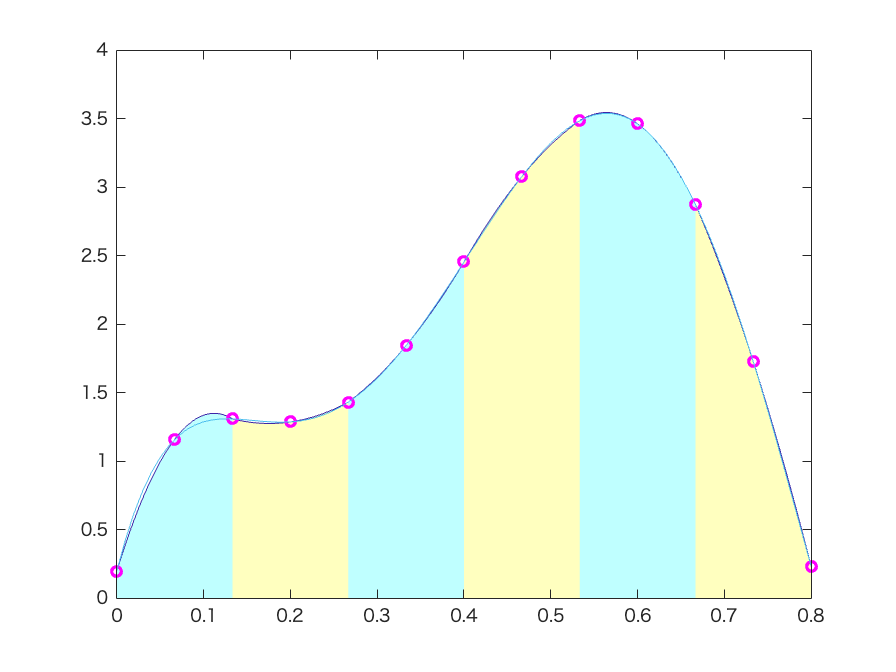

f=@(x) 400.*x.^5 - 900.*x.^4 + 675.*x.^3 - 200.*x.^2 + 25.*x + 0.2;

xx = 0 : 0.01 : 0.8;
yy = f(xx);

plot(xx, yy, '-')

To integrate function from 0 to 0.8

format long
a = 0;
b = 0.8;
p = [400 -900 675 -200 25 0.2];
q = polyint(p) % integrate polynomial equation (gives us the EXACT integration)

q = 1.0e+02 *

   0.666666666666667  -1.800000000000000   1.687500000000000  -0.666666666666667   0.125000000000000   0.002000000000000                   0


Itrue = diff(polyval(q, [a, b])) % for relative value

Itrue =    1.640533333333333


Plot original function along with simpson 1/3 rule with ns = 1

ns = 1

ns =      1


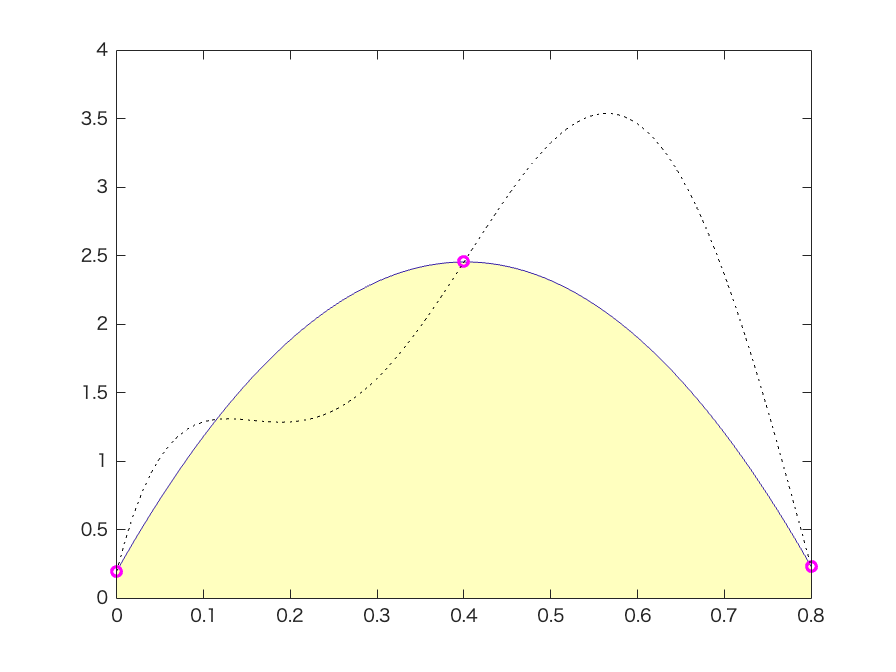

x = linspace(a, b, 2*ns+1);
y = f(x);

p2 = polyfit(x, y, 2);
yy2 = polyval(p2, xx);

figure
area(xx, yy2, 'FaceColor','y','FaceAlpha',0.25,'EdgeColor','flat','LineStyle','-')
hold on
plot(x, y, 'mo', 'LineWidth', 2)
hold on
plot(xx, yy, 'k:')

Plot original function along with simpson 1/3 rule from n = 1 to 10

ns = 6

ns =      6


k =      1


Segment #1: left-end = 0.0000, right-end = 0.8000 (+2h from a) x0 = 0.0000


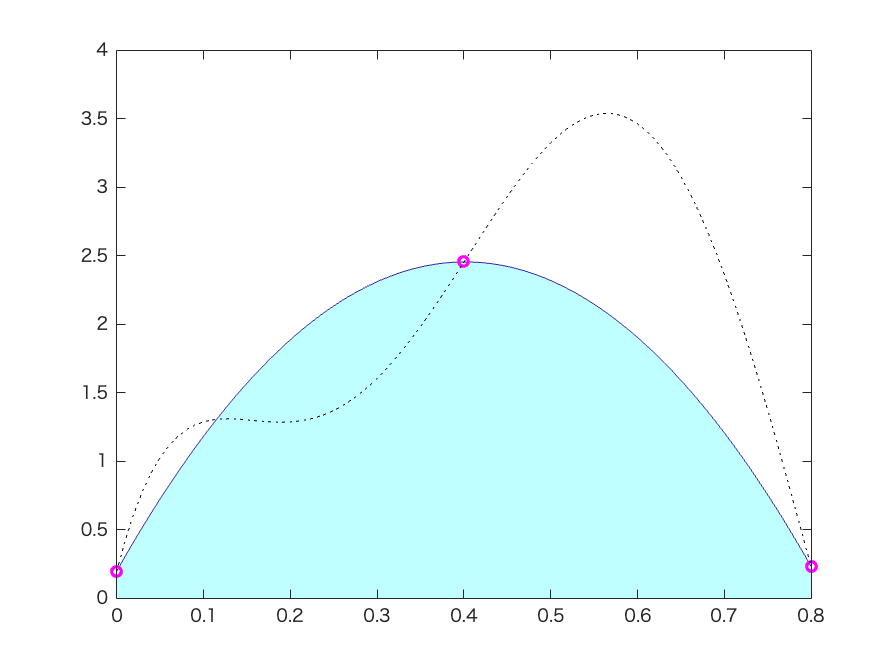

k =      2


Segment #1: left-end = 0.0000, right-end = 0.4000 (+2h from a) x0 = 0.0000
Segment #2: left-end = 0.4000, right-end = 0.8000 (+4h from a) x0 = 0.4000


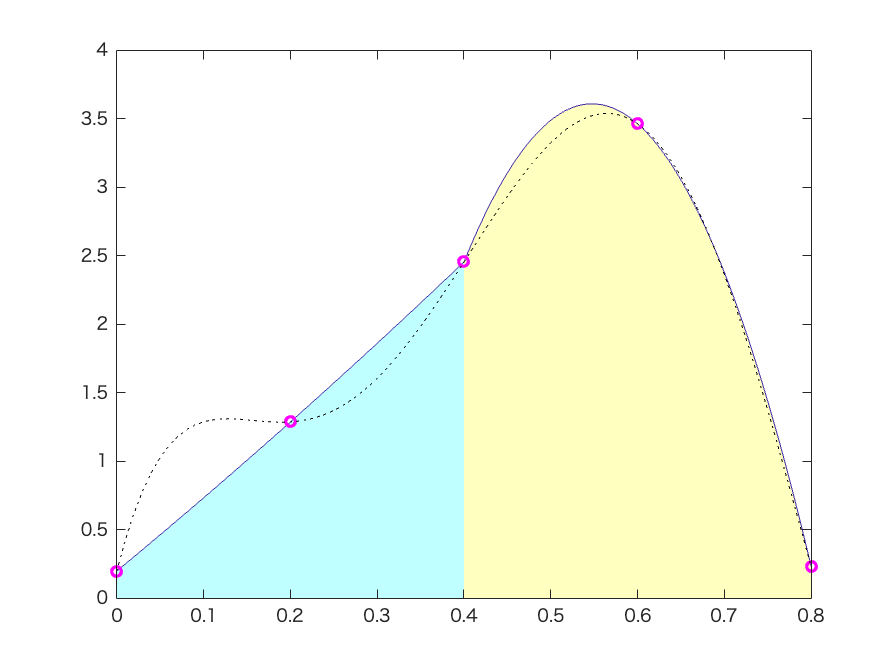

k =      3


Segment #1: left-end = 0.0000, right-end = 0.2667 (+2h from a) x0 = 0.0000
Segment #2: left-end = 0.2667, right-end = 0.5333 (+4h from a) x0 = 0.2667
Segment #3: left-end = 0.5333, right-end = 0.8000 (+6h from a) x0 = 0.5333


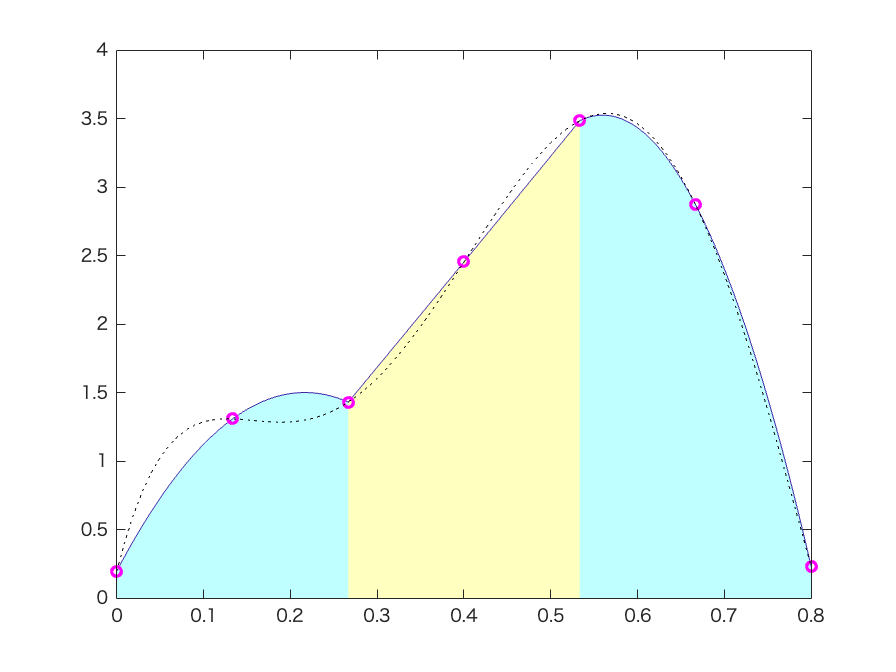

k =      4


Segment #1: left-end = 0.0000, right-end = 0.2000 (+2h from a) x0 = 0.0000
Segment #2: left-end = 0.2000, right-end = 0.4000 (+4h from a) x0 = 0.2000
Segment #3: left-end = 0.4000, right-end = 0.6000 (+6h from a) x0 = 0.4000
Segment #4: left-end = 0.6000, right-end = 0.8000 (+8h from a) x0 = 0.6000


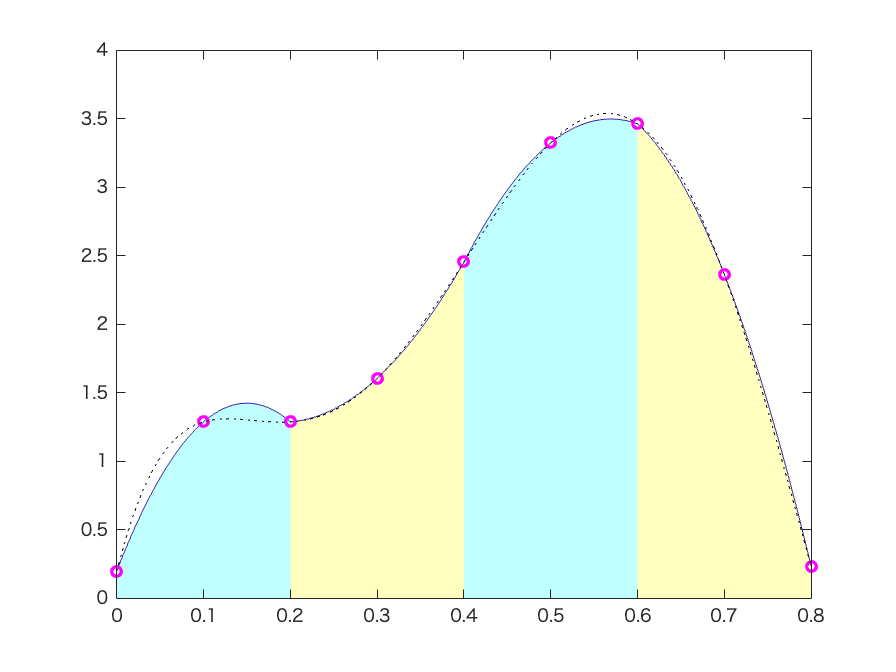

k =      5


Segment #1: left-end = 0.0000, right-end = 0.1600 (+2h from a) x0 = 0.0000
Segment #2: left-end = 0.1600, right-end = 0.3200 (+4h from a) x0 = 0.1600
Segment #3: left-end = 0.3200, right-end = 0.4800 (+6h from a) x0 = 0.3200
Segment #4: left-end = 0.4800, right-end = 0.6400 (+8h from a) x0 = 0.4800
Segment #5: left-end = 0.6400, right-end = 0.8000 (+10h from a) x0 = 0.6400


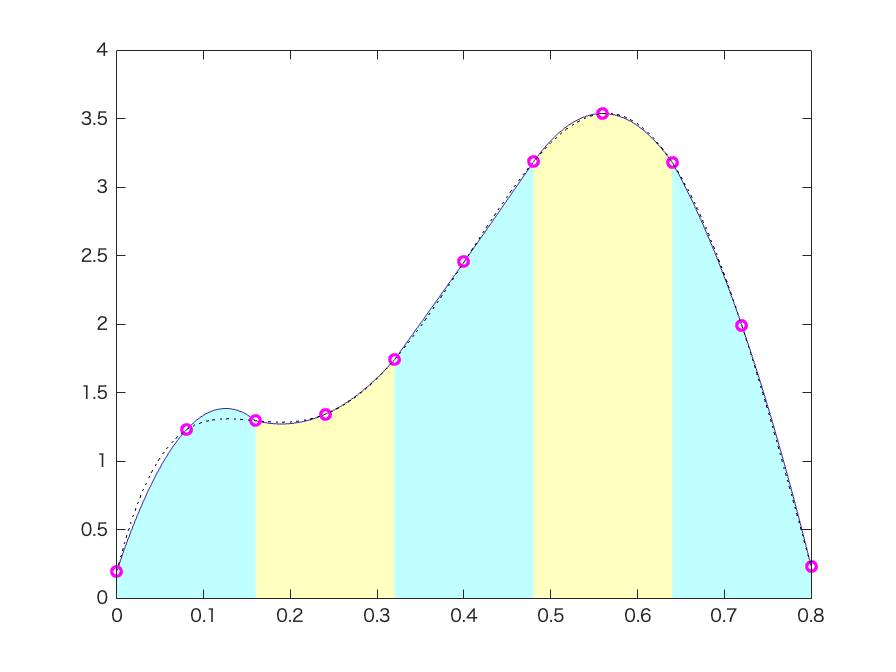

k =      6


Segment #1: left-end = 0.0000, right-end = 0.1333 (+2h from a) x0 = 0.0000
Segment #2: left-end = 0.1333, right-end = 0.2667 (+4h from a) x0 = 0.1333
Segment #3: left-end = 0.2667, right-end = 0.4000 (+6h from a) x0 = 0.2667
Segment #4: left-end = 0.4000, right-end = 0.5333 (+8h from a) x0 = 0.4000
Segment #5: left-end = 0.5333, right-end = 0.6667 (+10h from a) x0 = 0.5333
Segment #6: left-end = 0.6667, right-end = 0.8000 (+12h from a) x0 = 0.6667


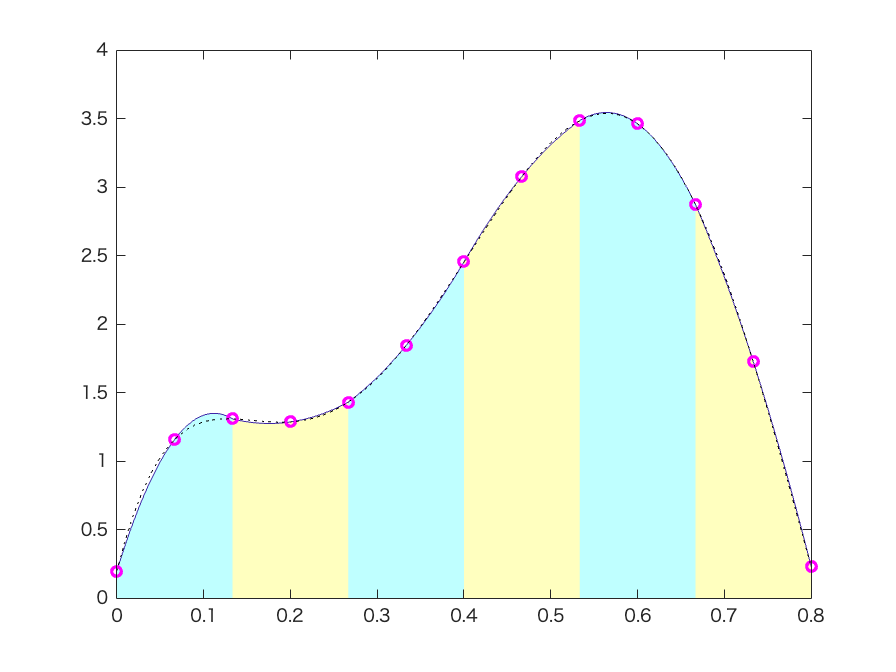


for k = 1:ns
    k
    x = linspace(a, b, 2*k+1);
    y = f(x);
    figure
    colors = ['y','c'];
    for i = 1:k
        h = (b - a)/(2*k);
        ileft = 2*(i-1)+1; % for left-end dots
        iright = 2*i+1; % for right-end dots
        x0 = (2*(i-1)*h)+a; % for left-end values
        fprintf("Segment #%d: left-end = %.4f, right-end = %.4f (+%dh from a) x0 = %.4f\n", i, x(ileft), x(iright), (i*2), x0)
        newx = x(ileft:iright);
        newy = y(ileft:iright);
        p2 = polyfit(newx, newy, 2);
        xx2 = linspace(x(ileft), x(iright));
        yy2 = polyval(p2, xx2);
        area(xx2, yy2, 'FaceColor',colors(mod(i,2)+1),'FaceAlpha',0.25,'EdgeColor','flat')
        hold on
        plot(newx, newy, 'mo', 'LineWidth', 2)
        hold on
    end
    plot(xx, yy, 'k:')
    %hold off
end